READ ME

This code is only made for Q2: Both ends fixed bar

-This is a code to find the displacement field of a beam using the method of FEM.

-Boundary condition 1 for both ends.

-k can be 0 or any other number.

-axial force distribution can be a number or a function of x.

-polynomial "HIERARCHICAL" basis function is used.

Clear all stored variables and commands

clear all
clc

Define basic settings

format long % for bettter accuracy
syms x % symbolic toolbox for handling polynomials

Getting the basic inputs

EA = input('EA = ')

EA =      1


k = input('spring constant assosciated with the member, k = ')

k =      0


L = input('Length of Beam = ')

L =      1


N = input('Order of polynomial = ')+1

N =      9


f = input('Distribution (use small letter "x" if it is a variable) of axial force = ')

$$f = 10\,x$$

Boundary condition at x = 0

    while true
        type_0 = input('Enter the type of boundary condition(1,2,or3) at x = 0:   ')

        if type_0 == 1
            U_0 = input('Give the displacement at the end x = 0 :  ')
            break
        elseif type_0 == 2
            P_0 = input('Give the force at the end x = 0 :  ')
            break
        elseif type_0 == 3
            k_spring = input('Give the value of connected spring constant :  ') % Please understand the difference between K , k , k_spring
            delta_0 = input('Give the extension of the connected spring at the end x = 0 :  ')
            break
        else
            fprintf('Error, Boundary condition must be any of of type 1 / type 2 or type 3 ')
            continue
        end
    end

type_0 =      1


U_0 =      0


Boundary condition at x = L

    while true
        type_L = input('Enter the type of boundary condition(1,2,or3) at x = L:   ')

        if type_L == 1
            U_L = input('Give the displacement at the end x = L :  ')
            break
        elseif type_L == 2
            P_L = input('Give the force at the end x = L :  ')
            break
        elseif type_L == 3
            k_spring = input('Give the value of connected spring constant :  ') % Please understand the difference between K , k , k_spring
            delta_L = input('Give the extension of the connected spring at the end x = L :  ')
            break
        else
            fprintf('Error, Boundary condition must be any of of type 1 / type 2 or type 3 ')
            continue
        end
    end

type_L =      1


U_L =      0


Initializing

Phi = sym(zeros(N,1));
K = zeros(N); % Please understand the difference between K , k , k_spring: This K is the stiffness matrix
F = zeros(N,1);

Establishing the Basis functions

Phi(1) = 1-(x/L);
Phi(2) = x/L;
if N>2
    Phi(3) = x*(L-x);
    if N>3
        for i = 4:N
            Phi(i) = Phi(3);
            for j = 1:i-3
                Phi(i) = Phi(i)*(((j)*(L/(i-2)))-x);
            end
        end
    end
end
for i = 3:N
    Phi(i-1) = Phi(i);
end
Phi(end) = x;
dPhi = diff(Phi);
Phi

$$Phi = \left(\begin{array}{c} 1-x\\ -x\,\left(x-1\right)\\ x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)\\ -x\,\left(x-1\right)\,\left(x-\frac{1}{3}\right)\,\left(x-\frac{2}{3}\right)\\ x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{1}{4}\right)\,\left(x-\frac{3}{4}\right)\\ -x\,\left(x-1\right)\,\left(x-\frac{1}{5}\right)\,\left(x-\frac{2}{5}\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{4}{5}\right)\\ x\,\left(x-1\right)\,\left(x-\frac{1}{2}\right)\,\left(x-\frac{1}{3}\right)\,\left(x-\frac{2}{3}\right)\,\left(x-\frac{1}{6}\right)\,\left(x-\frac{5}{6}\right)\\ -x\,\left(x-1\right)\,\left(x-\frac{1}{7}\right)\,\left(x-\frac{2}{7}\right)\,\left(x-\frac{3}{7}\right)\,\left(x-\frac{4}{7}\right)\,\left(x-\frac{5}{7}\right)\,\left(x-\frac{6}{7}\right)\\ x \end{array}\right)$$

Calculating the Stiffness Matrix  and the Force vector

if type_0 && type_L == 2
    for i = 1:N
        for j = 1:N
            K(i,j) = int(EA*dPhi(i)*dPhi(j)+k*Phi(i)*Phi(j),x,0,L);
        end
        F(i,1) = int(f*Phi(i),x,0,L) + subs(P_L*Phi(i),x,L) - subs(P_0*Phi(i),x,0);
    end
end
if type_0 && type_L == 1
    for i = 1:N
        for j = 1:N
            K(i,j) = int(EA*dPhi(i)*dPhi(j)+k*Phi(i)*Phi(j),x,0,L);
        end
        F(i,1) = int(f*Phi(i),x,0,L);
    end
end
K

K =    1.000000000000000                   0                   0                   0                   0                   0                   0                   0  -1.000000000000000
                   0   0.333333333333333                   0   0.007407407407407                   0   0.000419047619048                   0   0.000031543923970                   0
                   0                   0   0.050000000000000                   0   0.002232142857143                   0   0.000154320987654                   0                   0
                   0   0.007407407407407                   0   0.005878894767784                   0   0.000390264550265                   0   0.000031496225542                   0
                   0                   0   0.002232142857143                   0   0.000666542658730                   0   0.000056993546577                   0                   0
                   0   0.000419047619048                   0   0.000390264550265           

F

F =    1.666666666666667
   0.833333333333333
  -0.083333333333333
   0.018518518518519
  -0.003720238095238
   0.001047619047619
  -0.000257201646091
   0.000078859809924
   3.333333333333333


Computing the Solution

if type_0 && type_L == 2
    if k == 0
        K(1,:) = 0;
        K(:,1) = 0;
        K(1,1) = 1;
        fprintf('Since k = 0, with boundary condition type-2 at both ends\n there are infinite possible solutions. Out of the infinite solutions possible, \n one solution where the displacement at x = 0 is displayed!')
    end
end
if type_0 && type_L == 1

    K(1,:) = 0;
    F(1) = 0;
    K(:,1) = 0;
    K(1,1) = 1;

    K(:,end) = 0;
    K(end,:) = 0;
    F(end) = 0;
    K(end,end) = 1;
end



Alpha = K\F;
U = vpa(Alpha'*Phi)

$$U = 0.00000000000000094228797204486723715719280157888\,x\,\left(x-1.0\right)\,\left(x-0.33333333333333333333333333333333\right)\,\left(x-0.66666666666666666666666666666667\right)-1.6666666666666666666666666666667\,x\,\left(x-0.5\right)\,\left(x-1.0\right)-2.5\,x\,\left(x-1.0\right)-0.00000000000000044710088255141119577164530162698\,x\,\left(x-0.25\right)\,\left(x-0.5\right)\,\left(x-1.0\right)\,\left(x-0.75\right)-0.0000000000000065266114739520530101105202012498\,x\,\left(x-1.0\right)\,\left(x-0.6\right)\,\left(x-0.2\right)\,\left(x-0.4\right)\,\left(x-0.8\right)-0.0000000000000035969491274379095102631254121661\,x\,\left(x-0.5\right)\,\left(x-1.0\right)\,\left(x-0.16666666666666666666666666666667\right)\,\left(x-0.33333333333333333333333333333333\right)\,\left(x-0.66666666666666666666666666666667\right)\,\left(x-0.83333333333333333333333333333333\right)+0.00000000000001855066756183420277243451263314\,x\,\left(x-1.0\right)\,\left(x-0.14285714285714285714285714285714\right)\,\left(x-0.28571428571428571428571428571429\right)\,\left(x-0.57142857142857142857142857142857\right)\,\left(x-0.71428571428571428571428571428571\right)\,\left(x-0.42857142857142857142857142857143\right)\,\left(x-0.85714285714285714285714285714286\right)$$

`Plotting 

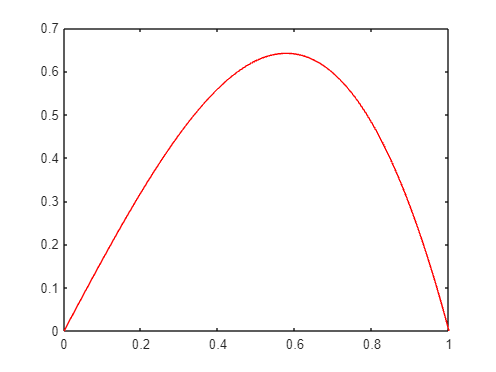

t = linspace(0,L,100);
u = subs(U,x,t);
figure()
plot(t,u,'r','Linewidth',0.2)